# Solving ODEs using Laplace Transform in MATLAB

## Exercise 1

Objective: Compute the Laplace transform and use it to show that MATLAB 'knows' some of its properties.

Details: 

(a) Define the function `f(t)=exp(2t)*t^3`, and compute its Laplace transform `F(s)`. (b) Find a function `f(t)` such that its Laplace transform is  `(s - 1)*(s - 2))/(s*(s + 2)*(s - 3)` (c) Show that MATLAB 'knows' that if `F(s)` is the Laplace transform of  `f(t)`, then the Laplace transform of `exp(at)f(t)` is `F(s-a)` 

(in your answer, explain part (c) using comments). 

Observe that MATLAB splits the rational function automatically when solving the inverse Laplace transform.

clear all;
syms t s x y
% (a) 
% Function definitions
f = exp(2*t)*t^3;
F = laplace(f); %F = 6/(s - 2)^4
disp(F)

$$\frac{6}{{\left(s-2\right)}^{4}}$$


% (b) %Computing f(t) given Laplace
G = ((s - 1)*(s - 2))/(s*(s + 2)*(s - 3));

g = ilaplace(G); % g = (6*exp(-2*t))/5 + (2*exp(3*t))/15 - 1/3
disp(g)

$$\frac{6\,{\mathrm{e}}^{-2\,t}}{5}+\frac{2\,{\mathrm{e}}^{3\,t}}{15}-\frac{1}{3}$$


% (c) Showing MATLAB "knows" the shift...
syms f(t) a
F = laplace(f) % F = laplace(f(t), t, s)

$$F = \mathrm{laplace}\left(f\left(t\right),t,s\right)$$

G =laplace(exp(a*t)*f) % G = laplace(f(t), t, s - a); SHIFTED 

$$G = \mathrm{laplace}\left(f\left(t\right),t,s-a\right)$$

% Clearly, from the results, MATLAB knows that when F(s) is shifted
% by F(s-a), the function is multiplied by exp(a*t) no matter what the
6/(s - 2)^4 

$$ans = \frac{6}{{\left(s-2\right)}^{4}}$$

(6*exp(-2*t))/5 + (2*exp(3*t))/15 - 1/3

$$ans = \frac{6\,{\mathrm{e}}^{-2\,t}}{5}+\frac{2\,{\mathrm{e}}^{3\,t}}{15}-\frac{1}{3}$$

F =laplace(f(t), t, s)

$$F = \mathrm{laplace}\left(f\left(t\right),t,s\right)$$

G =laplace(f(t), t, s - a)

$$G = \mathrm{laplace}\left(f\left(t\right),t,s-a\right)$$

## Heaviside and Dirac functions

## Exercise 2

Objective: Find a formula comparing the Laplace transform of a translation of `f(t)` by `t-a` with the Laplace transform of `f(t)`

Details: 

- Give a value to `a`

- Let `G(s)` be the Laplace transform of `g(t)=u_a(t)f(t-a)` and `F(s)` is the Laplace transform of `f(t)`, then find a formula relating `G(s)` and `F(s)`

In your answer, explain the 'proof' using comments.

clear all;
syms f(t) g(t) a s

% Give a value to |a|
a = 1;

% Let g(t) be f(t) translated by |t-a|
g = heaviside(t-a)*f(t-a);

% Let F be the Laplace transform of f(t)
F = laplace(f)
% Let G be the Laplace transform of g(t)
G = laplace(g)

% Start of PROOF
% Give a different value for |a|

$$F = \mathrm{laplace}\left(f\left(t\right),t,s\right)$$

a = 9;
% Let g(t) be f(t) translated by |t-a|

$$G = {\mathrm{e}}^{-s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

g = heaviside(t-a)*f(t-a);
% Let G be the Laplace transform of g(t)
G = laplace(g)

% F = laplace(f(t), t, s), while G = exp(-s)*laplace(f(t), t, s)
% Showing a 
% relationship between F,G, where G = exp(-a*s)*F
F = laplace(f(t), t, s)

$$G = {\mathrm{e}}^{-9\,s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

G = exp(-s)*laplace(f(t), t, s)
G = exp(-9*s)*laplace(f(t), t, s)

## Solving IVPs using Laplace transforms

## Exercise 3

Objective: Solve an IVP using the Laplace transform

Details: Explain your steps using comments

- Solve the IVP

- `y'''+2y''+y'+2*y=-cos(t)`

- `y(0)=0`, `y'(0)=0`, and `y''(0)=0`

- for `t` in `[0,10*pi]`

- Is there an initial condition for which `y` remains bounded as `t` goes to infinity? If so, find it.

clear all;

$$F = \mathrm{laplace}\left(f\left(t\right),t,s\right)$$

syms t Y s y(t) 

$$G = {\mathrm{e}}^{-s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

$$G = {\mathrm{e}}^{-9\,s}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

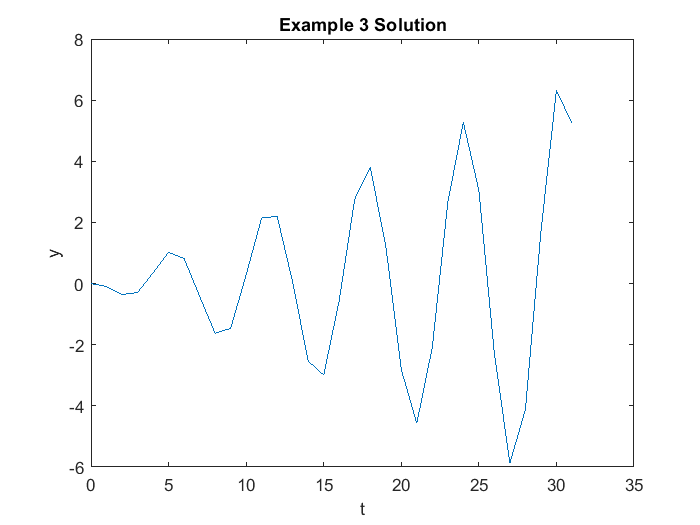

% Define ODE
ODE = diff(y(t),t,3) + 2*diff(y(t),t,2) + diff(y(t),t,1) + 2*y(t) == -cos(t);

% Compute Laplace transform of the ODE
m_tau = laplace(ODE);

% Use initial conditions
m_tau = subs(m_tau,y(0),0);
m_tau = subs(m_tau, subs(diff(y(t), t), t, 0), 0);
m_tau = subs(m_tau, subs(diff(y(t), t, 2), t, 0),0);

% Factor out the Laplace transform of y(t)
m_tau = subs(m_tau,laplace(y(t), t, s), Y);
Y = solve(m_tau,Y);

% inverse Laplace Transform
y = ilaplace(Y);

% Plot solution
t_range = 0:10*pi;
y_2 = subs(y,t,t_range);
plot(t_range,y_2)
ylabel ('y');
xlabel('t');
title ('Example 3 Solution');
% Exact solution: y(t) = c1*e^(-2t)+c2*sin(t)+c3*cos(t)-(1/5)*t*sin(t)+(1/10)*t*cos(t)
% Based on this, no initial conditions would give bounded
% solutions. The solution contains (t/5)*sin(t) and
% (t/10)*cos(t), both of which are terms that are independent of the initial conditions
% They are independant of ICs because they since
% they are not multiplied by the constants c1, c2, c3, all of which are found based off the 
% initial conditions.
% As t goes to infinity, these terms remain unbounded.

% As a result, the solution will diverge no matter what the initial conditions are.

## Exercise 4

Objective: Solve an IVP using the Laplace transform

Details: 

- Define 

- `g(t) = 3 if 0 < t < 2`

- `g(t) = t+1 if 2 < t < 5`

- `g(t) = 5 if t > 5`

- Solve the IVP

- `y''+2y'+5y=g(t)`

- `y(0)=2 and y'(0)=1`

- Plot the solution for `t` in `[0,12]` and `y` in `[0,2.25]`.

In your answer, explain your steps using comments.

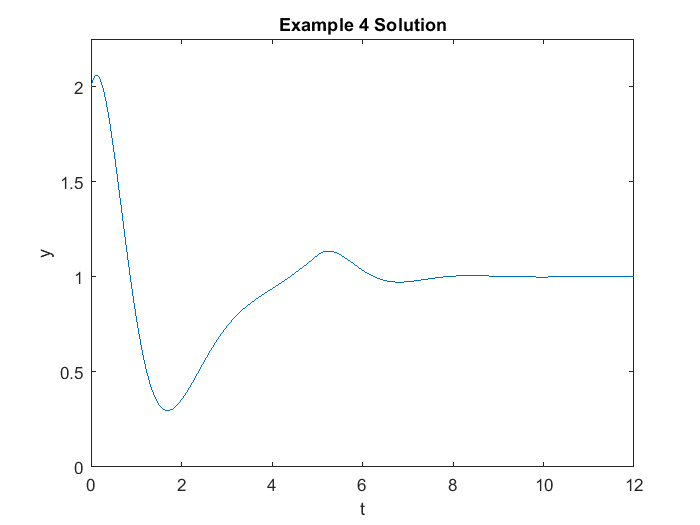

clear all;
syms s t y(t) Y
%Define ODE
%Define forcing function g(t)--> can be represented as a sum series of heaviside functions
g(t) = 3*heaviside(t) + (t-2)*heaviside(t-2) + (4-t)*heaviside(t-5);
ODE = diff(y(t),t,2) + 2*diff(y(t),t,1) + 5*y(t) == g(t);

% Compute Laplace transform of ODE
m_tau = laplace(ODE);

% Apply initial conditions
m_tau = subs(m_tau,y(0),2);
m_tau = subs(m_tau, subs(diff(y(t), t), t, 0), 1);

%Get Laplace transform of y(t)
m_tau = subs(m_tau,laplace(y(t), t, s), Y);
Y = solve(m_tau,Y);

% inverse Laplace transform
y = ilaplace(Y);

% Plot solution
ezplot(y,[0,12,0,2.25]);
ylabel ('y');
xlabel('t');
title ('Example 4 Solution');